# Treasure Hunt Game

% Initialize the number of guesses the player has made
numGuesses = 0;

% Select the board size (note that the board size will be one less than the numbers
% you choose)
rows = 12;
columns = 16;

% Set the boundaries for the map
boundaryX = columns - 1;
boundaryY = rows - 1;

% Randomly generate treasure location
treasureX = randi(boundaryX);
treasureY = randi(boundaryY); 

% Create the matrix of zeros
gameMap = zeros(rows, columns);

% Convert the zeros to NaN
gameMap(:) = NaN;

% Define all possible X and Y coordinates
xCoords = 1:columns;
yCoords = 1:rows;

% Create the taxicab matrix
solutionMap = abs(treasureX - xCoords) + abs(treasureY - yCoords)';

% Set the treasure to a high value so it appears correctly
solutionMap(treasureY,treasureX) = rows+columns+1;

% Define the colormap for the board with different colors to simulate an island
cmap = [0.6706 0.4588 0.0392; 0.4667 0.6745 0.1882; 0 1 0;1 0.9059 0.5216;0.0588 1 1; 0 0 1; 0 0.4471 0.7412;0.0314 0 0.4706; 1 1 0];

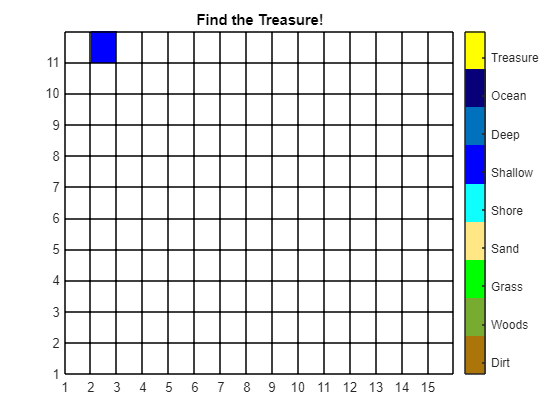

You are 17 away from the treasure.
Guess: 1
Guess again!


% Board setup
p = pcolor(gameMap);
hold on;
colormap(cmap);
c = colorbar;
clim([0 rows+columns+1]);
xticks(1:1:boundaryX);
yticks(1:1:boundaryY);
c.TickLabels = {'Dirt','Woods','Grass','Sand','Shore','Shallow','Deep','Ocean', 'Treasure'};
c.Ticks = 1:(rows+columns+1)/9:(rows+columns+1);
title("Find the Treasure!")

%Play Game

guessX = 2;
guessY = 11;

 

% Increment number of guesses
numGuesses = numGuesses + 1;

% Run function to check guesses
playGame(treasureX,treasureY,gameMap,solutionMap,guessX,guessY,numGuesses)

function playGame(treasureX,treasureY,gameMap,solutionMap,guessX,guessY,numGuesses)
    % If the treasure has been found
    if(guessX == treasureX)&&(guessY == treasureY)
        % Display the solutionMap
        pcolor(solutionMap);

        % Change the title to "Treasure Found!"
        title("Treasure Found!");

        hold off;
    % If the treasure has not been found
    else
        % Set the guessed location in map equal to the guessed location in
        % solutionMap
        gameMap(guessY,guessX) = solutionMap(guessY,guessX);

        % Display the updated map
        pcolor(gameMap);
        
        % Tell the player how far they are from the
        % treasure, and how many guesses they've taken so far
        help = "You are " + string(solutionMap(guessY,guessX)) + " away from the treasure.";
        guess = "Guess: " + numGuesses;
        disp(help);
        disp(guess);
        disp("Guess again!");
    end
end